# 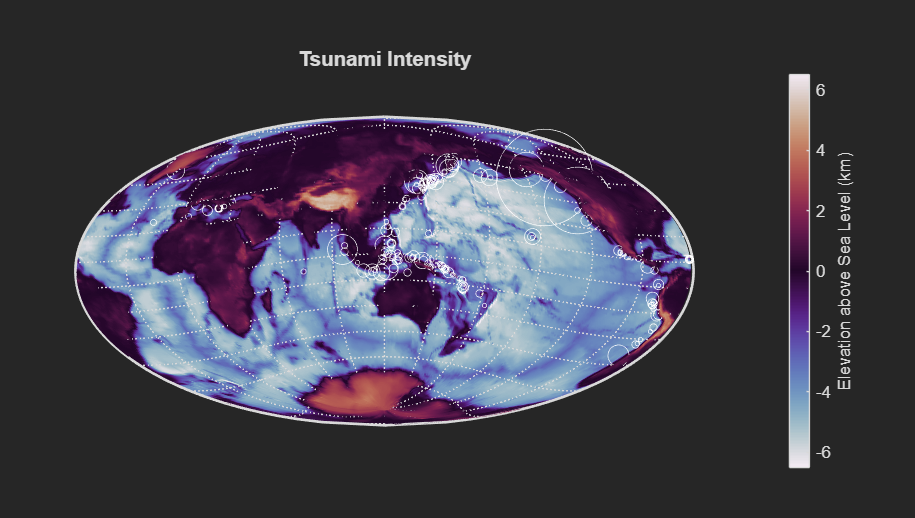

# Notebook1: Roadmap for Geospatial Mapping

## Introduction

Accessing and visualizing disparate data is a critical requirement for preparing for natural hazards, such as tsunamis or hurricanes. However, sometimes just connecting to and processing the data to prepare it for visualization and analysis can be result in large hurdles and time sinks. MATLAB has many capabilities for working with and visualizing data, including multiple new features that make handling and viewing geospatial data easier and requiring less coding.

Highlights of this workshop include:

- Access geospatial data, such as GIS shape files, netCDF, and other common data types

- Visualize data with different maps and figures

- Customize maps with relevant features

- Automate your data import, analysis, and mapping workflows

- Manage large datasets and best MATLAB coding practices for speeding up your code

- Find further mapping and geospatial resources

## 1. Import Excel Data

MATLAB has multiple different ways to access data. You can use the [`Import Data`](https://www.mathworks.com/help/matlab/ref/importtool.html?searchHighlight=import%20tool&s_tid=srchtitle_support_results_1_import%2520tool) tool, double click on files in the File Browser, or use any number of direct 'read' functions.

Q:What is one function you can use to access Excel or CSV files? 

Alternatively, live scripts include the option of adding live controls and live tasks to easily set up an interactive GUI in your code. Use the live task below to browse for and import your data.

Live tasks (and, in fact, almost any UI function) can help you learn to code.  If you > Show code, you will see the exact lines of code that the live task used to import your data. You can also choose to convert the live task directly to code after you're done.

The `Cause` variable attributes a cause to each tsunami, such as, 'Earthquake', 'Volcano', or 'Earthquake and Landslide'. Convert the `Cause` variable from a cell array of character vectors into a categorical variable by calling the command [`categorical`](https://www.mathworks.com/help/matlab/ref/categorical.html?searchHighlight=categorical&s_tid=srchtitle_support_results_1_categorical) on the `Cause` field.

### Data Preprocessing

Oftentimes your data isn't in the perfect state for your analyses. There are a number of preprocessing live tasks that you can use to clean up your data. However, this workshop focuses on data visualizations, so we'll simply run a few lines of code to preprocess our data.

% set NaN's in these columns to zeros
% convert to time or timetable

[tsunamis,missingIndices] = fillmissing(tsunamis,"constant",0,...
    'DataVariables',{'Year','Month','Day','Hour','Minute','Second'})
dt = datetime(tsunamis.Year, tsunamis.Month, tsunamis.Day, tsunamis.Hour, tsunamis.Minute, tsunamis.Second);
T = table2timetable(tsunamis(:,7:end),'RowTimes',dt);
% How can you change your lines of code into a function?

% separate the data into pre and post 1970.
datesplit = datetime("1970-01-01", "InputFormat", "uuuu-MM-dd");
old_tsunami = T(T.Time<datesplit,:);
recent_tsunami =  T(T.Time>datesplit,:);

Get your figure looking good interactively. Then, copy the autogenerated code so that it automatically plots that way every time afterward.

Are more tsunamis ocurring after 1970? What could be causing the increase in our dataset? Why do our plots look different from one another? Can we make a direct comparison?

figure
tiledlayout(1,2) % this is the new/replacement for subplot you may be familiar with

nexttile(1)


nexttile(2)



How would you use a pie chart to compare the relative amount (%) of each tsunami cause?

figure
tiledlayout(1,2)

nexttile(1)


nexttile(2)


## 2. Visualize Data on Interactive Maps

Create a geographic bubble chart, [`geobubble`](https://www.mathworks.com/help/matlab/ref/geobubble.html?s_tid=doc_ta), to plot the locations of the tsunamis on an interactive map. With a geobubble figure, you can

- Specify latitude and longitude

- Plot max tsunami height as the size of the bubble

- Use categorical variables to specify the color of the bubbles

(To use one of the default basemaps, you will need an internet connection. If you do not have internet, you can [create your own basemap](matlab:open('..\WIP\BaseMapCreationsol.mlx')) and save it locally.) 

figure
geobubble(tsunamis,'Latitude','Longitude', ...
    'SizeVariable','MaxHeight','ColorVariable','Cause')

Experiment with the map. Pan and scroll to `zoom in` on an area of interest and update the `map limits.` How would you change the `Basemap` that is displayed in the background? What are other properties of `geobubble` that you can change?

### Geoaxes - Fixed Projection

The examples above use geoaxes to display data. Geoaxes display data with latitude and longitude coordinates on a live map with a fixed projection (usually mercator). Typically, you do not need to create geographic axes before plotting because geographic plotting functions, such as geobubble, automatically create geographic axes when they do not exist.

What are some of the properties and options available to you with geoaxes? How do you access and change these properties?

figure
geox = geoaxes

## 3. Other Map Projections and Options

### 'axesm' and 'worldmap'

[`Axesm`](https://www.mathworks.com/help/map/ref/axesm.html) creates an axesm-based map, which is a specialized type of map axis that allows for both vector and raster geographic data to be projected. It provides more specific control over map projections and properties. You can set properties upon creation or modify them later using [`getm`](https://www.mathworks.com/help/map/ref/getm.html?searchHighlight=getm&s_tid=srchtitle_support_results_1_getm) and [`setm`](https://www.mathworks.com/help/map/ref/setm.html?searchHighlight=setm&s_tid=srchtitle_support_results_1_setm).

#### Projections

Let's re-plot the region of interest to view our data with a different map projection. What happens when you type the following lines of code?

figure
axm = axesm('robinson')

There are a few extra options built on axesm for common maps and workflows. What are some of the options you see when calling [`worldmap`](https://www.mathworks.com/help/map/ref/worldmap.html?s_tid=doc_ta)? What function can you call to get a list of map projections you can plot?

Call [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html?searchHighlight=hold%20on&s_tid=srchtitle_support_results_1_hold%2520on)` on` to indicate that you want to plot more information on the same axes. You only have to call `hold on` once, and all subsequent commands will plot on the same axes until you call `hold off` or create a new [`figure`](https://www.mathworks.com/help/matlab/ref/figure.html?s_tid=doc_ta).

MALTAB has functions for specifically plotting data on map axes, such as [`plotm`](https://www.mathworks.com/help/map/ref/plotm.html?s_tid=doc_ta) and [`scatterm`](https://www.mathworks.com/help/map/ref/scatterm.html?s_tid=doc_ta). What is the first input required for `plotm`? Plot the coordinates of the world's coastlines on the same `worldmap` axes you created above.

- Call `load coastlines`, and find latitudes stored in `coastlat `and longitudes stored in `coastlon`.

How would you change the color of the coastlines?

#### Further Customization

Experiment with the location and appearance of latitude and longitude tick marks and labels by adjusting axes properties such as `meridianlabel`, `parallellabel`, and `MLabelParallel`. Find the proper syntax by first calling `help setm. T`hen specify which figure axis you want to edit, such as 

% Font Characteristics
font_size = 9;
font_color = [0.067 0.443 0.745];
map_title = "My Title";

% Map Label Locations
m_lab_loc = "south";
p_lab_loc = "east";

setm(gca, 'meridianlabel', 'on','MLabelParallel',m_lab_loc,'parallellabel','on',...
    'PLabelMeridian',p_lab_loc,'FontColor',font_color,'FontSize',font_size) % changed by above live controls
title(map_title)

How would you choose the frequency of the parallel and meridian labels? Where in the documentation can you look?

*© The MathWorks, Inc., 2025*